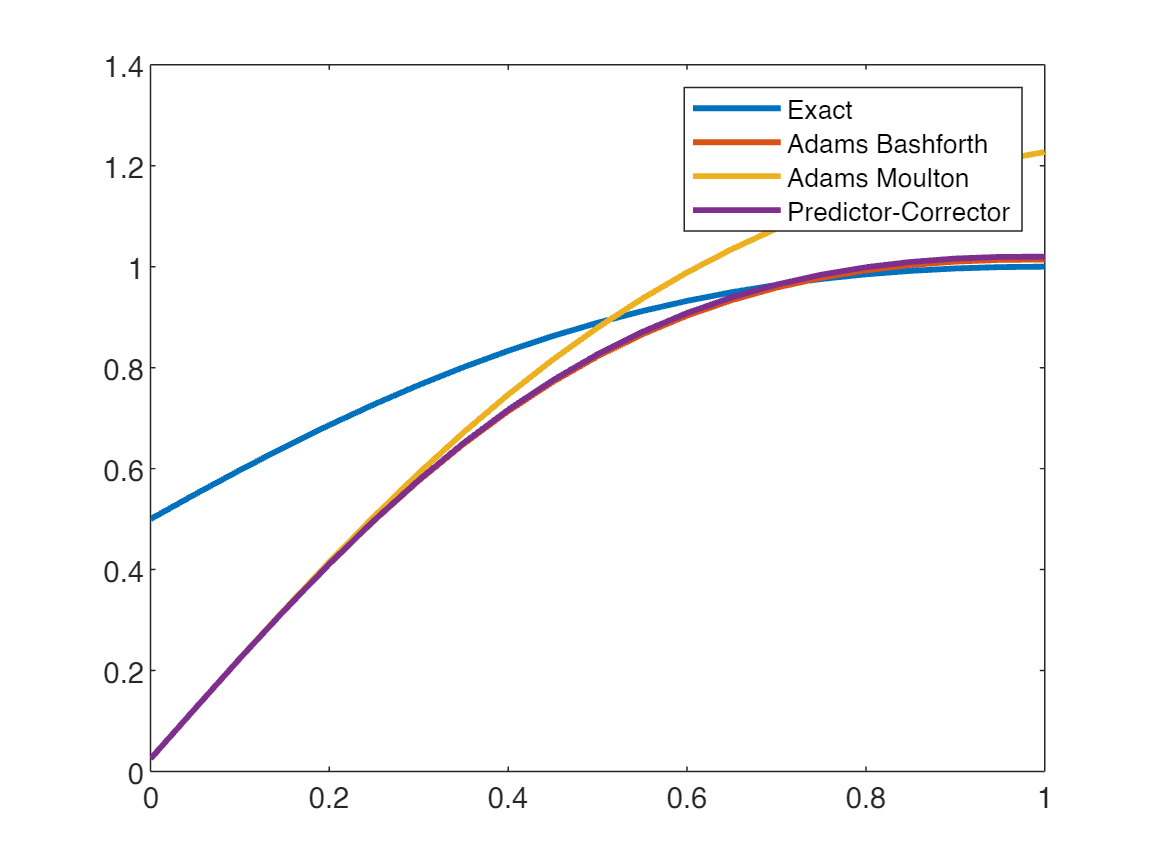

syms t y f(t,y) exact(t)
f(t,y)=(2-2*t*y)/(t^2+1);
exact(t)=(2*t +1)/(t^2 +2);

h=0.05;
t=[0:h:1];
y0=0.025;

Table=zeros(length(t),8);

for i=1:length(t)
    Table(i,1)=t(i);
    Table(i,2)=exact(t(i));
end


% 4 Step Adams Bashforth

Table(1,3)=y0;
for i=1:3
   Table(i+1,3)=Table(i,3)+h*f(t(i),Table(i,3));
end

for i=4:length(t)-1
    Table(i+1,3) = Table(i,3)+h*(55*f(t(i),Table(i,3))-59*f(t(i-1),Table(i-1,3))+37*f(t(i-2),Table(i-2,3))-9*f(t(i-3),Table(i-3,3)))/24;
end

%err_AB
for i=1:length(t)
    Table(i,6)=abs(Table(i,2)-Table(i,3));
end



% 3 Step Adams Moulton 

for i=1:2
    Table(i,4)=Table(i,3);
end

for i=2:length(t)-1
    Table(i+1,4)=Table(i,4)+h*(5*f(t(i+1),Table(i+1,4))+8*f(t(i),Table(i,4))-f(t(i-1),Table(i-1,4)))/12;
end

%err_AB
for i=1:length(t)
    Table(i,7)=abs(Table(i,2)-Table(i,4));
end



% 3 Step Adams Moulton

for i=1:3
    Table(i,5)=Table(i,3);
end
 
for i=3:length(t)-1
    Table(i+1,5)=Table(i,5)+ h*(9*f(t(i+1),Table(i,3))+19*f(t(i),Table(i,5))-5*f(t(i-1),Table(i-1,5))+f(t(i-2),Table(i-2,5)))/24;
end

%err_AB
for i=1:length(t)
    Table(i,8)=abs(Table(i,2)-Table(i,5));
end

plot(Table(:,1),Table(:,2),Table(:,1),Table(:,3),Table(:,1),Table(:,4),Table(:,1),Table(:,5), 'LineWidth', 2.0)
legend("Exact","Adams Bashforth","Adams Moulton","Predictor-Corrector")


TableHeadings = {'t', 'exact', 'A-B', 'A-M', 'P-C', 'err_A-B', 'err_A-M', 'err_P_C'};
tab = array2table(Table,'VariableNames',TableHeadings);
table(tab)

ans = 21×1 table
       tab   
    _________

    1×8 table
    1×8 table
    1×8 table
    1×8 table
    1×8 table
    1×8 table
    1×8 table
    1×8 table
    1×8 table
    1×8 table
    1×8 table
    1×8 table
    1×8 table
    1×8 table
    1×8 table
    1×8 table
